# 2-D Plots

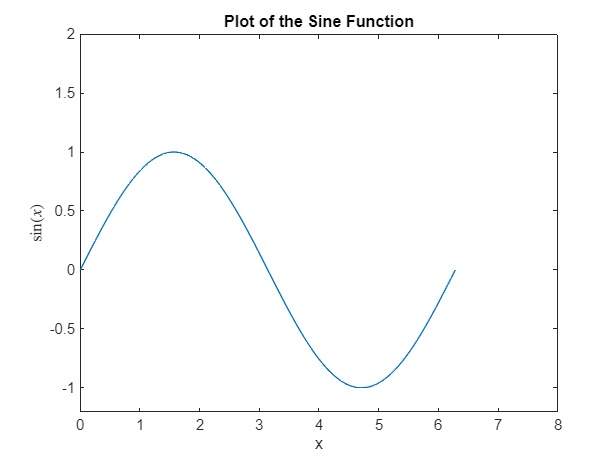

x = linspace(0,2*pi);
y = sin(x);
plot(x,y)

xlim([0 8])
ylim([-1.2 2])
xlabel("x")
ylabel("$\sin(x)$",Interpreter="latex")
title("Plot of the Sine Function")

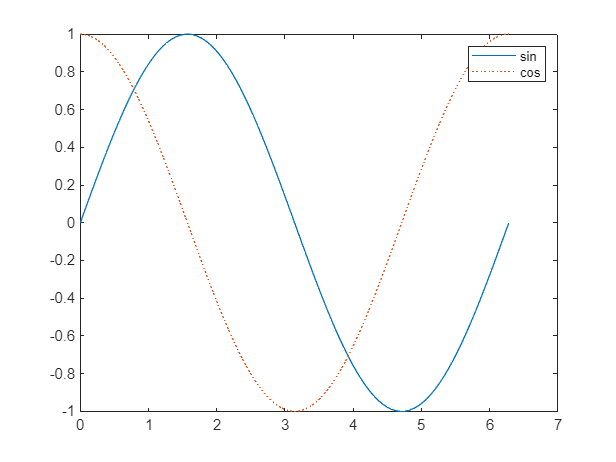

x = linspace(0,2*pi);
y = sin(x);
plot(x,y)

hold on

y2 = cos(x);
plot(x,y2,":")
legend("sin","cos")

hold off

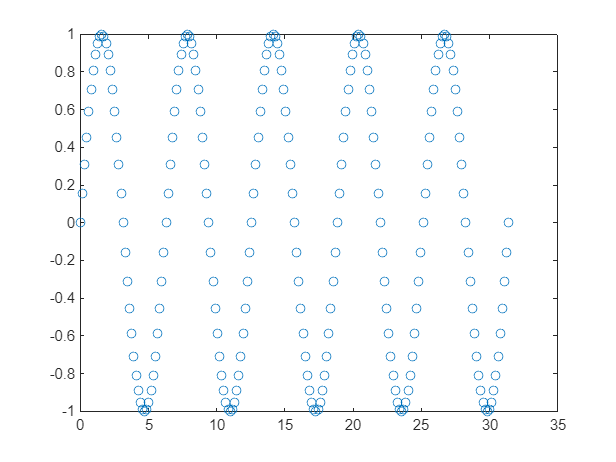

xt = 0:pi/20:10*pi;
yt = sin(xt);
plot(xt,yt,'o')

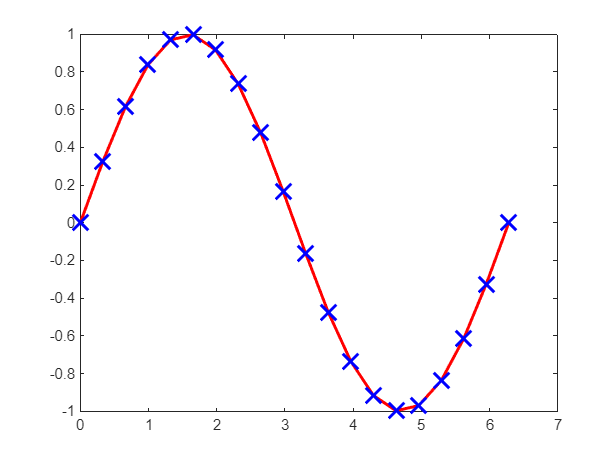

x = linspace(0,2*pi,20);
y = sin(x);
plot(x,y,Color='r',LineStyle="-",LineWidth=2,Marker="x",MarkerSize=15,MarkerEdgeColor='b',MarkerFaceColor='b')

## 3D Plot

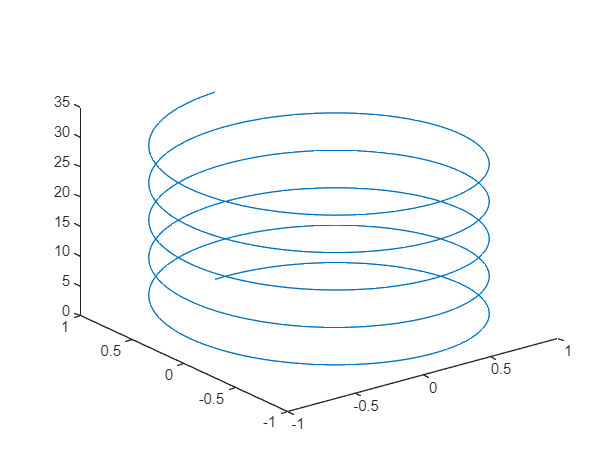

t = 0:pi/50:10*pi;
st = sin(t);
ct = cos(t);
plot3(st,ct,t)

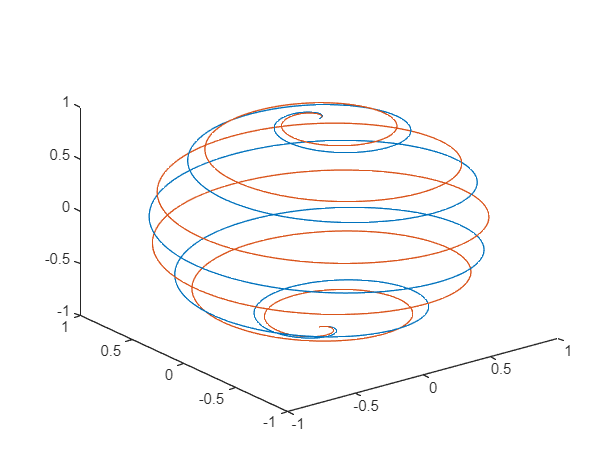

t = 0:pi/500:pi;
xt1 = sin(t).*cos(10*t);
yt1 = sin(t).*sin(10*t);
zt1 = cos(t);

xt2 = sin(t).*cos(12*t);
yt2 = sin(t).*sin(12*t);
zt2 = cos(t);
plot3(xt1,yt1,zt1,xt2,yt2,zt2)

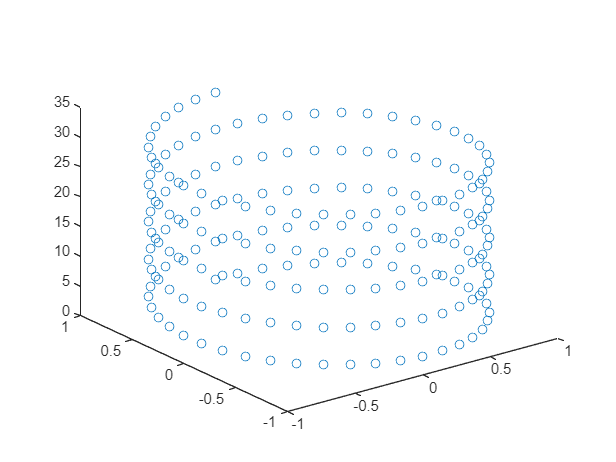

t = 0:pi/20:10*pi;
xt = sin(t);
yt = cos(t);
plot3(xt,yt,t,'o')

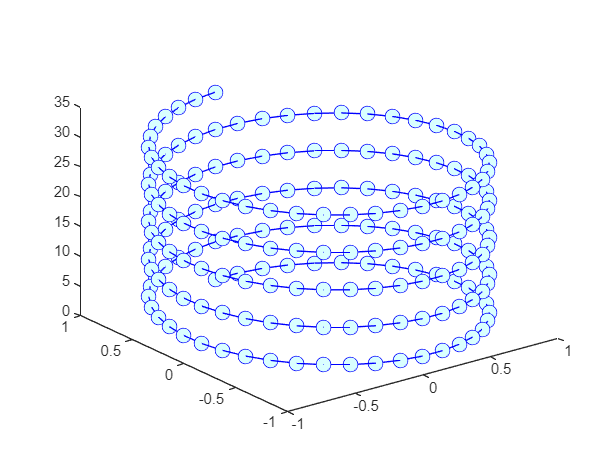

t = 0:pi/20:10*pi;
xt = sin(t);
yt = cos(t);
plot3(xt,yt,t,'-o','Color','b','MarkerSize',10,...
    'MarkerFaceColor','#D9FFFF')

## 3-D Surface

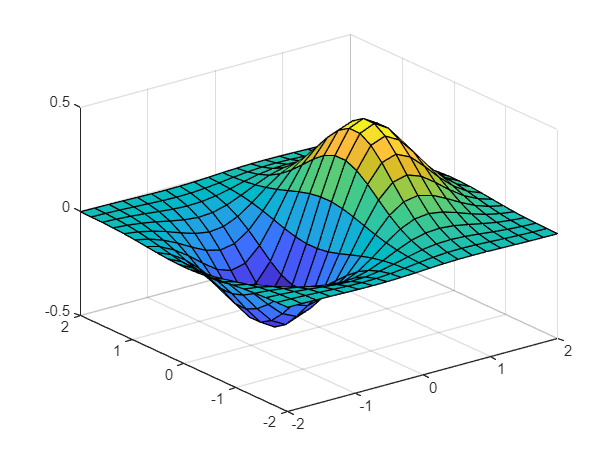

x = linspace(-2,2,20);
y = x';
z = x .* exp(-x.^2 - y.^2);
surf(x,y,z)

## Multiple Plots

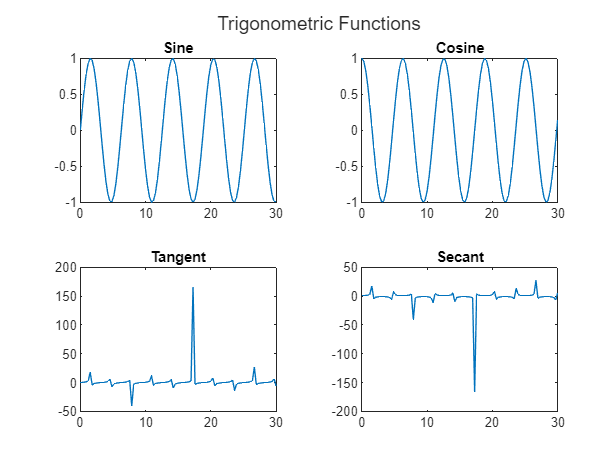

t = tiledlayout(2,2);
title(t,"Trigonometric Functions")
x = linspace(0,30);

nexttile
plot(x,sin(x))
title("Sine")

nexttile
plot(x,cos(x))
title("Cosine")

nexttile
plot(x,tan(x))
title("Tangent")

nexttile
plot(x,sec(x))
title("Secant")